## **Driver test program to check Clothoids library**

**Test G1 clothoid**

close all;

% initial point with angle direction
x0     = 0;
y0     = 0.1;
theta0 = 1.571;

% final point with angle direction
x1     = 0.085;
y1     = 0.035;
theta1 = 2.356;

fprintf('Testing G1 Clothoid interpolation\n');

Testing G1 Clothoid interpolation


fprintf('initial point (%g,%g) initial angle = %g\n', x0, y0, theta0);

initial point (0,0.1) initial angle = 1.571


fprintf('final point (%g,%g) final angle = %g\n', x1, y1, theta1);

final point (0.085,0.035) final angle = 2.356



% compute clothoid parameters
C = ClothoidCurve();
C.build_G1( x0, y0, theta0, x1, y1, theta1 );

fprintf('Computed parameters: k = %g, k'' = %g, L = %g\n', C.kappaBegin(), C.dkappa(), C.length() );

Computed parameters: k = -67.8821, k' = 715.752, L = 0.200614


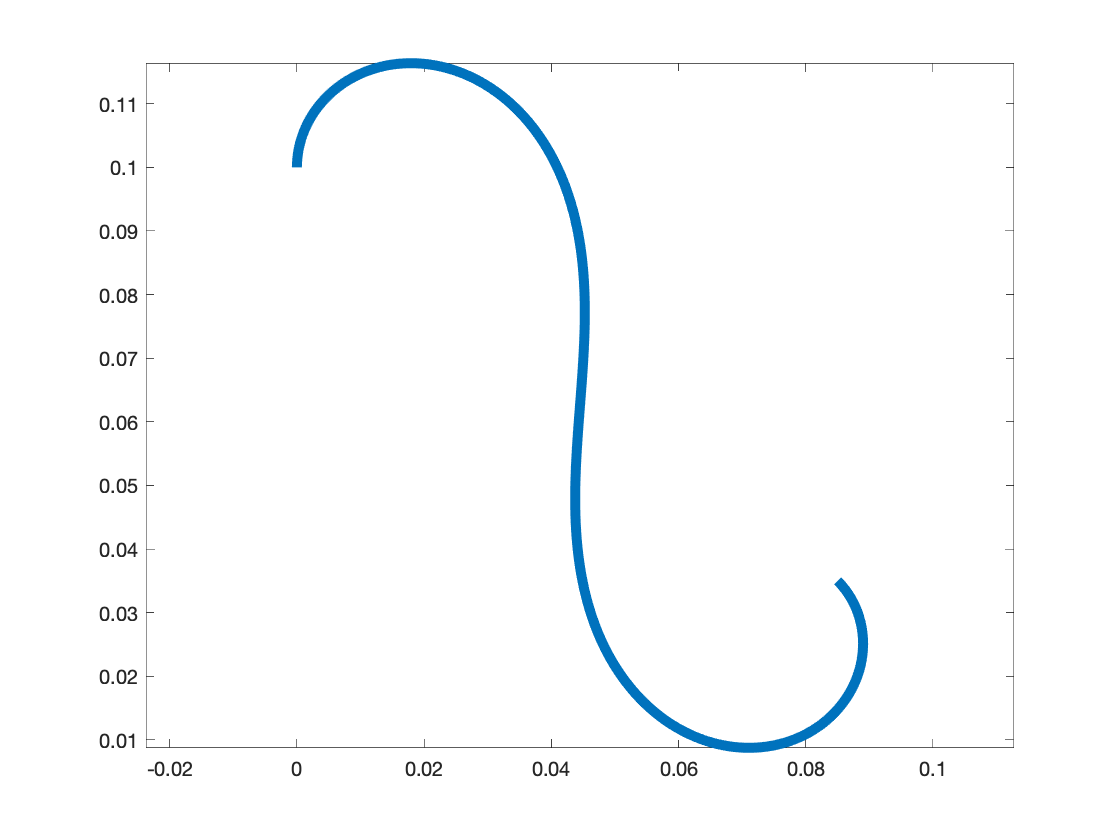

C.plot(1000,'Linewidth',5);
axis equal